mfccLength = 9;
class1 = 'TURMER';
class2 = 'LUSMEG';
bandEdges = linspace(50,22050,42);

TURMER_mfccTrain = TURMER_mfcc;
clear('TURMER_mfcc');
LUSMEG_mfccTrain = LUSMEG_mfcc;
clear('LUSMEG_mfcc');

TURMER_mfccTrain = buildMfccFeatureMatrix(class1,mfccLength,"BandEdges",bandEdges);
LUSMEG_mfccTrain = buildMfccFeatureMatrix(class2,mfccLength,"BandEdges",bandEdges);

signals = {};

directoryPath = sprintf('samples/%s/syllables/%s',class1,"train");
fileList = dir(fullfile(directoryPath, '*.wav'));   
limit = numel(fileList);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [signal,~] = audioread(filePath);
    signal = mono(signal);
    if numel(signal) < 2.4e4
        signals(size(signals,1)+1,:) = {signal};
    end
end

directoryPath = sprintf('samples/%s/syllables/%s',class2,"train");
fileList = dir(fullfile(directoryPath, '*.wav'));   
limit = numel(fileList);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [signal,~] = audioread(filePath);
    signal = mono(signal);
    if numel(signal) < 2.4e4
        signals(size(signals,1)+1,:) = {signal};
    end
end

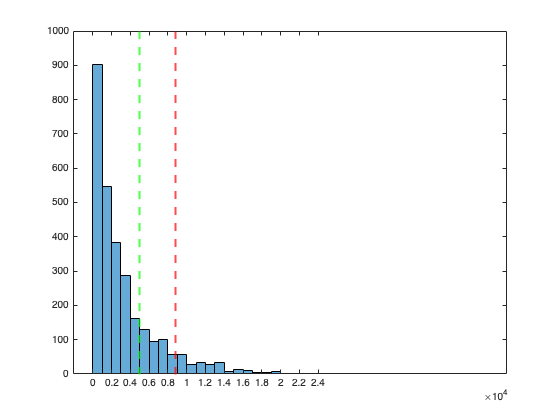

L = cellfun(@length,signals);
h = histogram(L);
hold on
xline(8820, 'r--', 'LineWidth', 2);
xline(5000, 'g--', 'LineWidth', 2);
hold off
xticks(0:2000:2.5e4);

XTrain = [TURMER_mfccTrain;LUSMEG_mfccTrain];
XTrainCell = mat2cell(XTrain, ones(size(XTrain, 1), 1), size(XTrain, 2));
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mfccTrain,1)) = -1;
YTrain = categorical(YTrain, [-1, 1], {class1,class2});

TURMER_mfccTest = buildMfccFeatureMatrix(class1,mfccLength,"BandEdges",bandEdges,"Type","test");
LUSMEG_mfccTest = buildMfccFeatureMatrix(class2,mfccLength,"BandEdges",bandEdges,"Type","test");

XTest = [TURMER_mfccTest;LUSMEG_mfccTest];
YTest = ones(size(XTest,1),1);
YTest(1:size(TURMER_mfccTest,1)) = -1;
YTest = categorical(YTest, [-1, 1], {class1,class2});
XTestCell = mat2cell(XTest, ones(size(XTest, 1), 1), size(XTest, 2));

layers = [
    sequenceInputLayer(1)
    lstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   LSTM                    LSTM with 100 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

options = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 150, ...
    'InitialLearnRate', 0.01, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment',"auto",...
    'plots','training-progress', ...
    'Verbose',false);

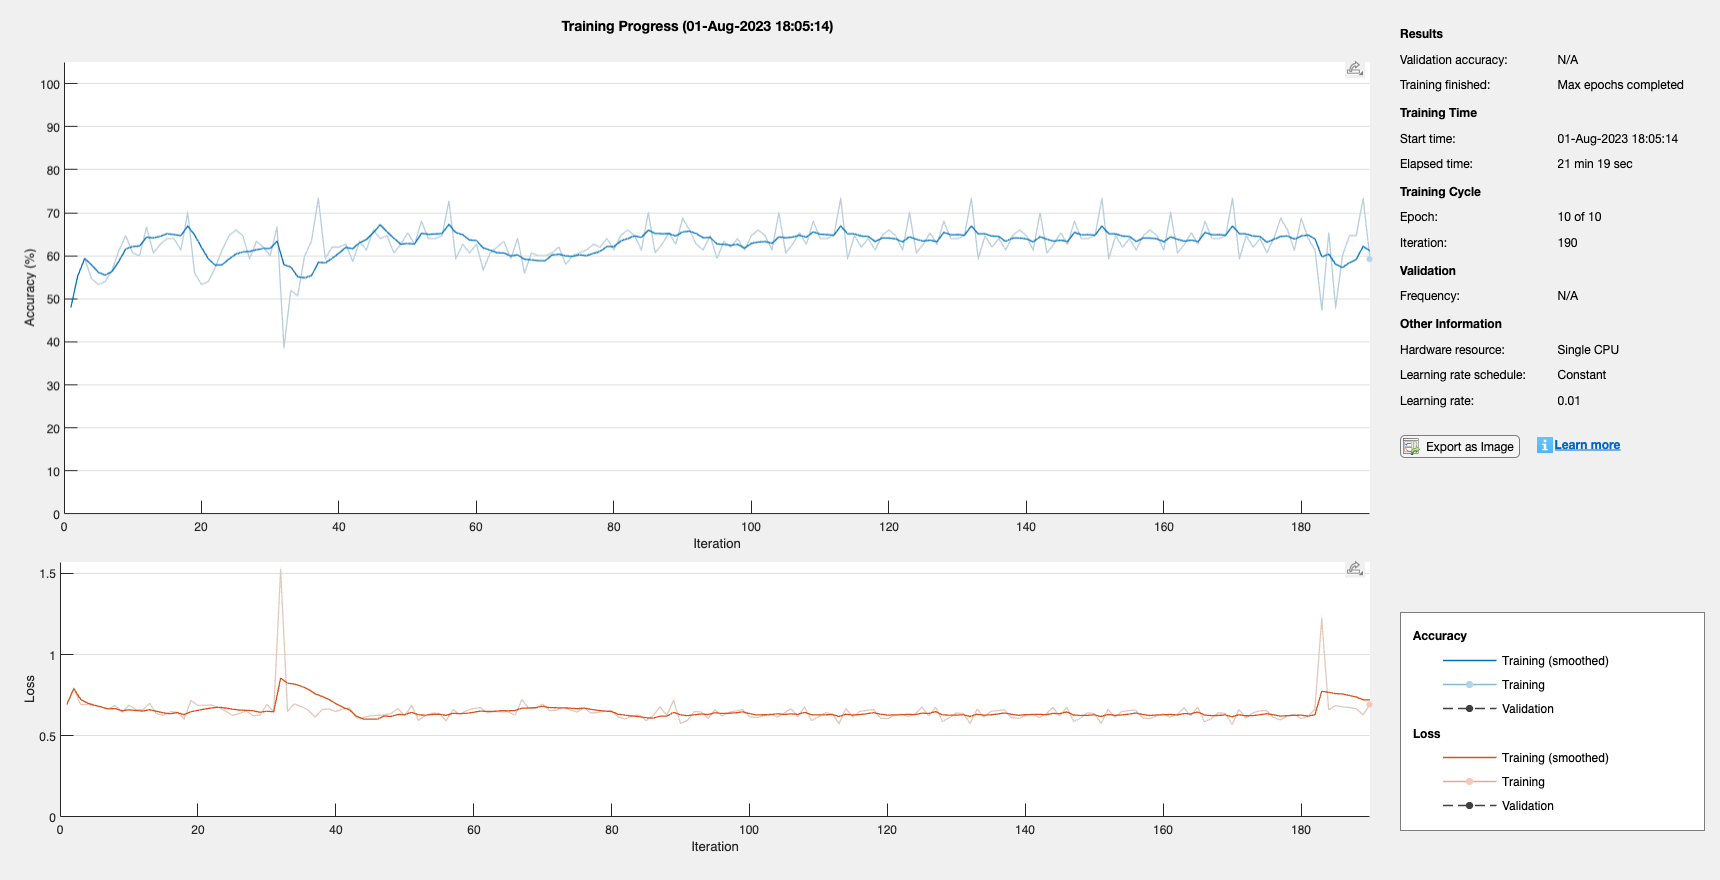

net = trainNetwork(XTrainCell,YTrain,layers,options);

### Trying Japanese vowels example approach

https://uk.mathworks.com/help/deeplearning/ug/classify-sequence-data-using-lstm-networks.html

directoryPath = sprintf('samples/%s/syllables/%s',class1,"train");
fileList = dir(fullfile(directoryPath, '*.wav'));
limit = 100;
mfccMatrix = {};
curId = "";
for i = 1:limit
    filename = fileList(i).name;
    tokens = regexp(filename, '(.*?)_', 'tokens');
    idTag = tokens{1}{1};
end

TURMER_mfccTrain = buildRawMfccMatrix(class1,"BandEdges",bandEdges);
LUSMEG_mfccTrain = buildRawMfccMatrix(class2,"BandEdges",bandEdges);

XTrain = cat(1,TURMER_mfccTrain,LUSMEG_mfccTrain);
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mfccTrain,1)) = -1;
YTrain = categorical(YTrain, [-1, 1], {class1,class2});

numObservations = numel(XTrain);
for i=1:numObservations
    sequence = XTrain{i};
    sequenceLengths(i) = size(sequence,2);
end

[sequenceLengths,idx] = sort(sequenceLengths);
XTrain = XTrain(idx);
YTrain = YTrain(idx);

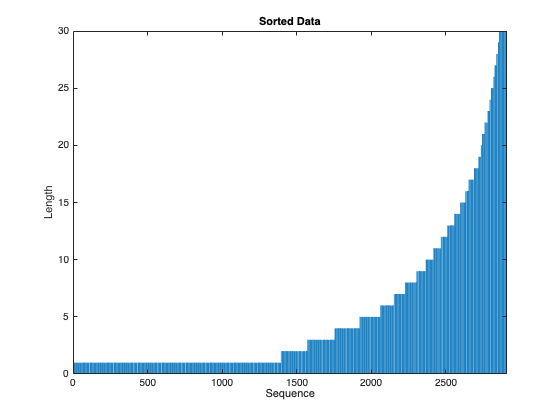

figure
bar(sequenceLengths)
ylim([0 30])
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

inputSize = 14;
numHiddenUnits = 100;
numClasses = 2;
miniBatchSize = 97;

layers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,OutputMode="last")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 14 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

options = trainingOptions("adam", ...
    ExecutionEnvironment="cpu", ...
    GradientThreshold=1, ...
    MaxEpochs=200, ...
    MiniBatchSize=miniBatchSize, ...
    SequenceLength="longest", ...
    Shuffle="never", ...
    Verbose=0, ...
    Plots="training-progress");

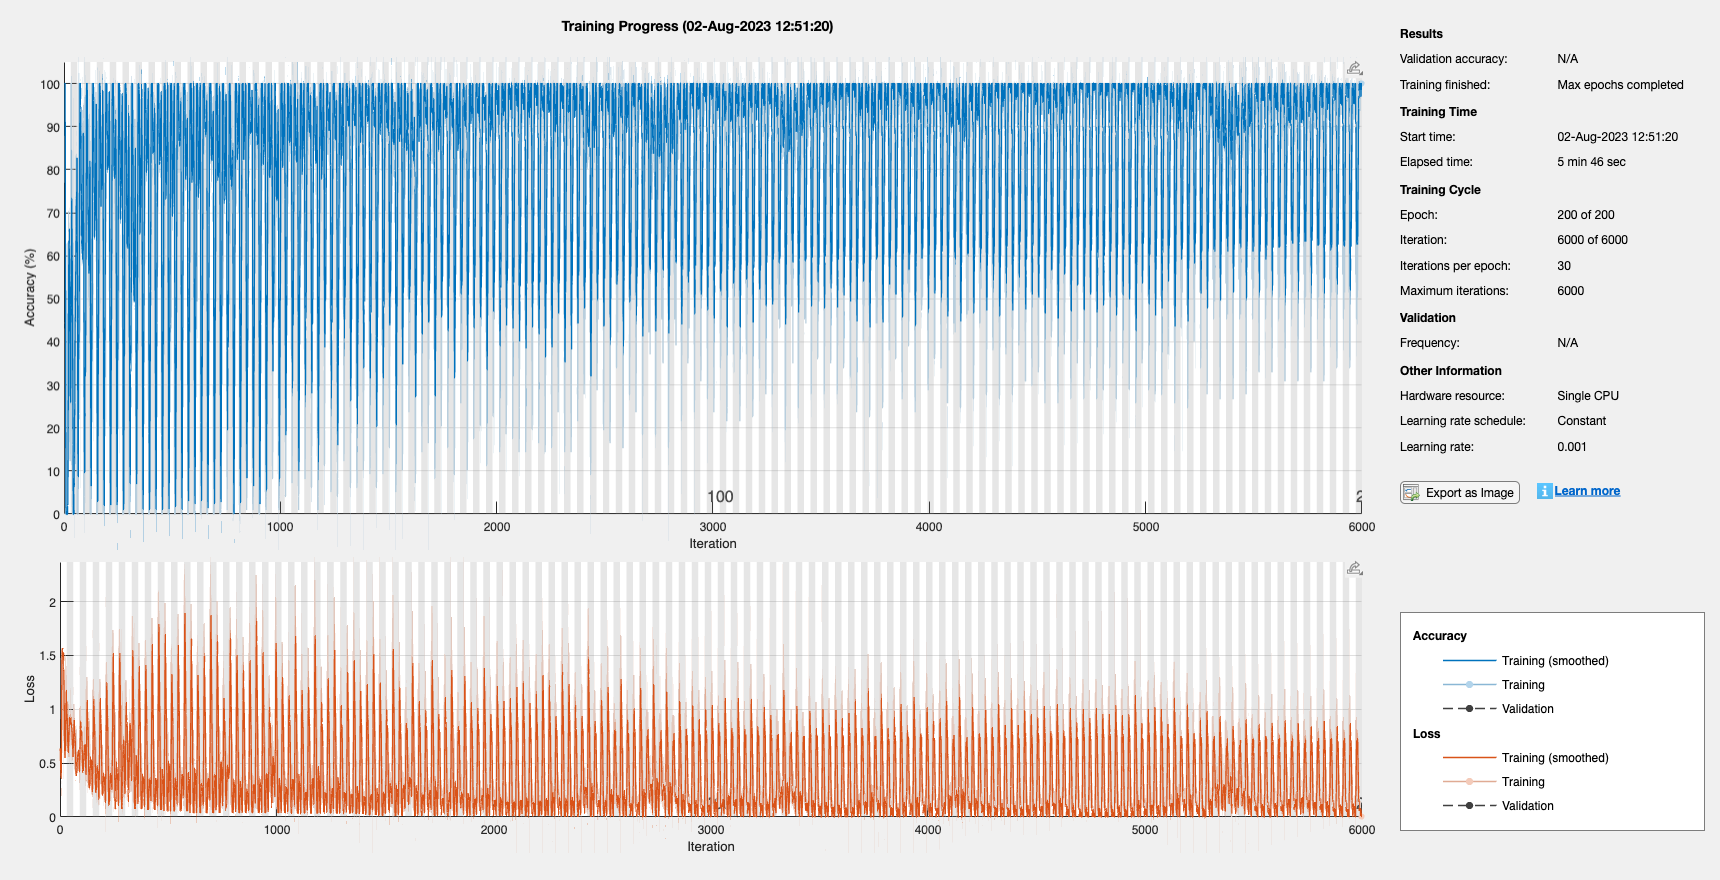

net = trainNetwork(XTrain,YTrain,layers,options);

TURMER_mfccTest = buildRawMfccMatrix(class1,"BandEdges",bandEdges,"Type","test");
LUSMEG_mfccTest = buildRawMfccMatrix(class2,"BandEdges",bandEdges,"Type","test");

XTest = cat(1,TURMER_mfccTest,LUSMEG_mfccTest);
YTest = ones(size(XTest,1),1);
YTest(1:size(TURMER_mfccTest,1)) = -1;
YTest = categorical(YTest, [-1, 1], {class1,class2});

numObservationsTest = numel(XTest);
for i=1:numObservationsTest
    sequence = XTest{i};
    sequenceLengthsTest(i) = size(sequence,2);
end

[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTest = XTest(idx);
YTest = YTest(idx);

YPred = classify(net,XTest, ...
    MiniBatchSize=miniBatchSize, ...
    SequenceLength="longest");

acc = sum(YPred == YTest)./numel(YTest)

acc = 0.8052

### Trying with MRCG

filtBanks.fs44100 = gammatoneFilterBank([50 20000],64,44100);
filtBanks.fs48000 = gammatoneFilterBank([50 20000],64,48000);

TURMER_mrcgTrain = buildRawMrcgMatrix(class1,filtBanks);
LUSMEG_mrcgTrain = buildRawMrcgMatrix(class2,filtBanks);

XTrain = cat(1,TURMER_mrcgTrain,LUSMEG_mrcgTrain);
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mrcgTrain,1)) = -1;
YTrain = categorical(YTrain, [-1, 1], {class1,class2});

numObservations = numel(XTrain);
for i=1:numObservations
    sequence = XTrain{i};
    sequenceLengths(i) = size(sequence,2);
end

[sequenceLengths,idx] = sort(sequenceLengths);
XTrain = XTrain(idx);
YTrain = YTrain(idx);

figure
bar(sequenceLengths)
ylim([0 30])
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

inputSize = 256;
numHiddenUnits = 100;
numClasses = 2;
miniBatchSize = 97;

layers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,OutputMode="last")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 256 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

options = trainingOptions("adam", ...
    ExecutionEnvironment="cpu", ...
    GradientThreshold=1, ...
    MaxEpochs=200, ...
    MiniBatchSize=miniBatchSize, ...
    SequenceLength="longest", ...
    Shuffle="never", ...
    Verbose=0, ...
    Plots="training-progress");

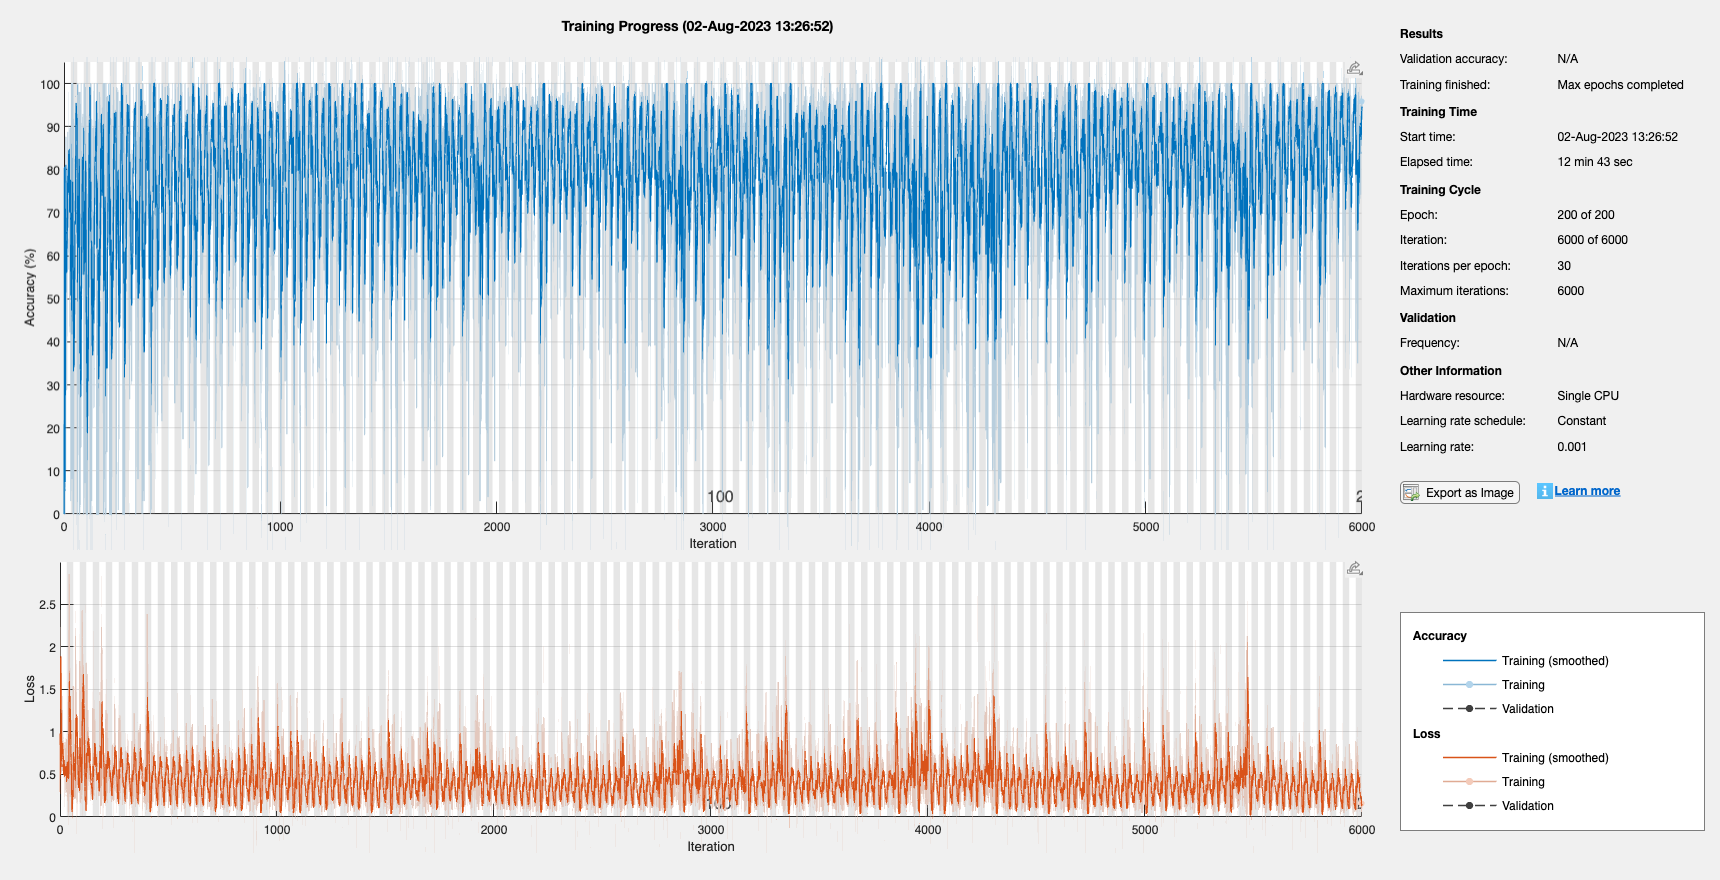

mrcgNet = trainNetwork(XTrain,YTrain,layers,options);

TURMER_mrcgTest = buildRawMrcgMatrix(class1,filtBanks,"Type","test");
LUSMEG_mrcgTest = buildRawMrcgMatrix(class2,filtBanks,"Type","test");

XTest = cat(1,TURMER_mrcgTest,LUSMEG_mrcgTest);
YTest = ones(size(XTest,1),1);
YTest(1:size(TURMER_mrcgTest,1)) = -1;
YTest = categorical(YTest, [-1, 1], {class1,class2});

numObservationsTest = numel(XTest);
for i=1:numObservationsTest
    sequence = XTest{i};
    sequenceLengthsTest(i) = size(sequence,2);
end

[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTest = XTest(idx);
YTest = YTest(idx);

YPred = classify(mrcgNet,XTest, ...
    MiniBatchSize=miniBatchSize, ...
    SequenceLength="longest");

acc = sum(YPred == YTest)./numel(YTest)

acc = 0.7563

function mfccMatrix = buildRawMfccMatrix(birdID,nva)
arguments
birdID
nva.Type = 'train'
nva.SampleLimit = false
nva.BandEdges = false
nva.MaxLength = 2.4e4
end
directoryPath = sprintf('samples/%s/syllables/%s',birdID,nva.Type);
fileList = dir(fullfile(directoryPath, '*.wav'));
if nva.SampleLimit
    limit = nva.SampleLimit;
else
    limit = numel(fileList);
end
mfccMatrix = {};
for i = 1:limit
    filePath = fullfile(directoryPath, fileList(i).name);
    [audio, fs] = audioread(filePath);
    audio = mono(audio);
    if numel(audio) < round(fs*0.03)
        padded = zeros(round(fs*0.03),1);
        padded(1:numel(audio)) = audio;
        audio = padded;
    end
    if numel(audio) > nva.MaxLength
        audio = audio(1:nva.MaxLength,:);
    end
    mfccFeature = mfcc(audio,fs,"BandEdges",nva.BandEdges);
    mfccMatrix(i,:) = {mfccFeature'};
end
end

function mrcgMatrix = buildRawMrcgMatrix(birdID,filtBanks,nva)
arguments
birdID
filtBanks
nva.Type = 'train'
nva.SampleLimit = false
nva.MaxLength = 2.4e4
end
directoryPath = sprintf('samples/%s/syllables/%s',birdID,nva.Type);
fileList = dir(fullfile(directoryPath, '*.wav'));
if nva.SampleLimit
    limit = nva.SampleLimit;
else
    limit = numel(fileList);
end
mrcgMatrix = {};
for i = 1:limit
    filePath = fullfile(directoryPath, fileList(i).name);
        [audio, fs] = audioread(filePath);
    audio = mono(audio);
    if numel(audio) < 500
        padded = zeros(round(fs*0.03),1);
        padded(1:numel(audio)) = audio;
        audio = padded;
    end
    if numel(audio) > nva.MaxLength
        audio = audio(1:nva.MaxLength,:);
    end
    gt = filtBanks.(sprintf('fs%d',fs));
    audioOut = gt(audio);
    mrcgFeature = mrcg(audioOut,fs);
    mrcgMatrix(i,:) = {mrcgFeature};
end
end